# Grafico Neutral Curve Rayleigh vs wavenumber

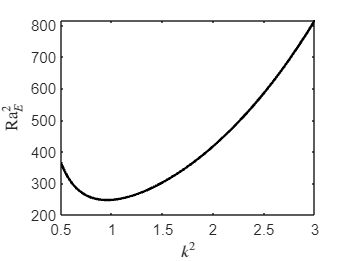

clear all
close all
clc

z=linspace(0,1,100);
tspan=[0 1];

index_zero=[2 4 8 9 ];
index_uno=[1 3 5 7  ];

H=10^(2);
gamma=1;
TU=5;
Da=0.01;

R_iniz=500;
mu=1.022;
kk=3:-0.01:0.5;

initcond=[0;3;0;9;0;1;0;3;R_iniz];
for i=1:length(kk)
    k=kk(i)*pi;
    [F,alphanew,niter,ifail] = newton_method_generale(@(z,y) ivp_system_pen(z,y,H,gamma,Da,TU,mu,k),initcond,index_zero,index_uno,tspan,z);
    initcond(index_zero)=alphanew;
    R(i)=alphanew(4);
    %kk(i)=alphanew(end);
end
plot(kk,R,'k-',LineWidth=1.5)
    xlabel('$k^2$',Interpreter='latex')
ylabel('$\mathrm{Ra}_E^2$',Interpreter='latex')


[rc,indexc]=min(R)

rc = 247.3903

indexc = 206

kc=kk(indexc)

kc = 0.9500


save neutral_curve_nonlinear_TU_5
return

clear all
close all
clc

z=linspace(0,1,100);
tspan=[0 1];

index_zero=[2 4 8 9 11 13 17 18];
index_uno=[1 3 5 7 10 12 14 16 ];

H=10^(2);
gamma=1;
TU=6;
Da=0.1;

mumu=1.1:-0.001:1.001;
R_iniz=575;

initcond1=[0;3;0;9;0;1;0;3;R_iniz;0;3;0;9;0;0;0;3;3];
for i=1:length(mumu)
    mu=mumu(i);
    [F,alphanew,niter,ifail] = newton_method_generale(@(z,y) ivp_system_viscosity(z,y,H,gamma,Da,TU,mu),initcond1,index_zero,index_uno,tspan,z);
    initcond1(index_zero)=alphanew;
    R1(i)=alphanew(4);
    %kk(i)=alphanew(end);
end
plot(mumu,R1,'k-',LineWidth=1.5)
    xlabel('$\mu$',Interpreter='latex')
ylabel('$\mathrm{Ra}_E^2$',Interpreter='latex')

[rc,indexc]=max(R1)
muc=mumu(indexc)

